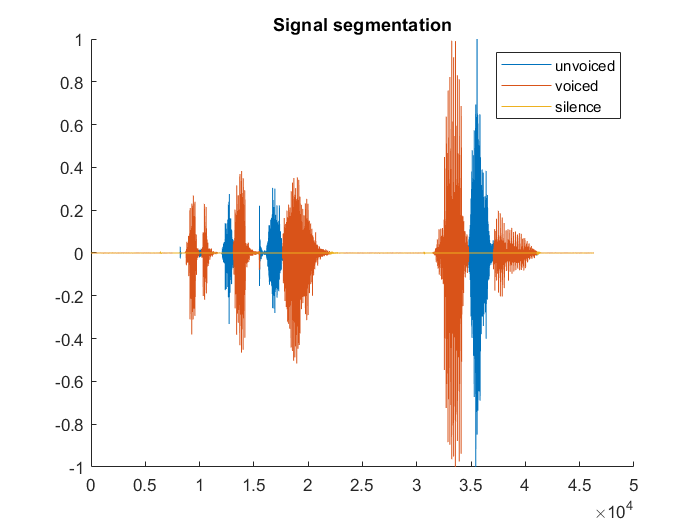

[x, fs] = audioread("percepcja.wav");
x = x / max(x);

global STR_th; % speech detection threshold based on STR
global VOICED_th; % threshold separating voiced and unvoiced sounds based on ZCR
STR_th = 0.06;
VOICED_th = 0.2376;

lbls = label(x, fs);
f0 = pitchwin(x, fs, round(fs * 0.1));

f0(lbls ~= 2) = 0;

silence = x;
silence(lbls ~= 0) = 0;

unvoiced = x;
unvoiced(lbls ~= 1) = 0;

voiced = x;
voiced(lbls ~= 2) = 0;

figure;
hold on;
plot(unvoiced);
plot(voiced);
plot(silence);
ylim([-1, 1]);
legend("unvoiced", "voiced", "silence");
title('Signal segmentation');

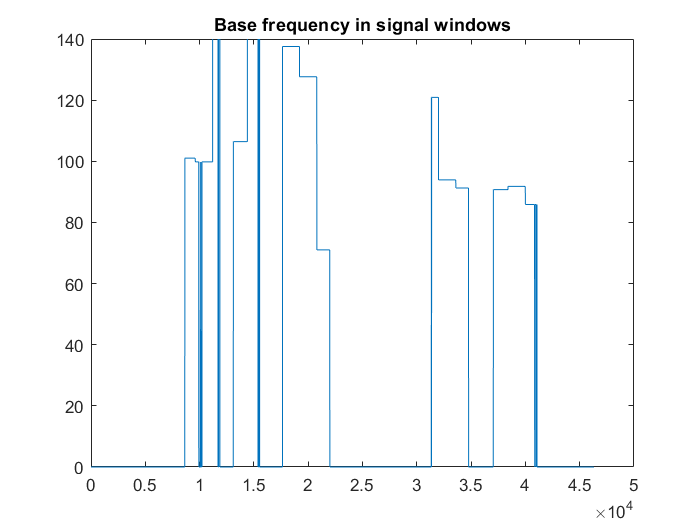


figure;
plot(f0);
ylim([0 140]);
title('Base frequency in signal windows');

function str = find_speach(x, fs)
    x = x - mean(x);
    x = x / max(x);
    win = round(fs * 0.2);
    ste = conv(x.^2, ones(1,win), 'same');
    ste = ste / max(ste);
    str = sqrt(ste);
end

function zcr = calc_zcr(x, fs, str)
    global STR_th;
    str_th = STR_th;
    win = round(fs * 0.005);
    x1 = x;
    x2 = [0; x(1:end-1)];
    diff = sign(x1) ~= sign(x2);
    zcr = conv(diff, ones(1, win) / win, "same");
    for i=1:length(x)
        if str(i) < str_th
            zcr(i) = 0;
        end
    end
end

function separated = separate_voiced_unvoiced(x,str, zcr)
    global STR_th;
    global VOICED_th;
    str_th = STR_th;
    voiced_th = VOICED_th;
    separated = zeros(length(x),1);
    for i=1:length(x)
        if str(i) > str_th
            if zcr(i) > voiced_th
                separated(i) = 1;
            else
                separated(i) = 2;            
            end
            
        end
    end
end

function lbls = label(x, fs)
    str = find_speach(x,fs);
    zcr = calc_zcr(x, fs, str);
    lbls = separate_voiced_unvoiced(x, str, zcr);
end


% function f0 = pitchwin(x, fs, window_size)
%     f0 = zeros(length(x),1);
%     str_th = 0.015;
%     str = find_speach(x,fs);
%     f_max = 300;
%     lag_min = fs / f_max;
%     for i=1:length(x) - window_size
%         crop_signal = x( (i) : window_size + i );
%         [c, lags] = xcorr(crop_signal, "normalized");
%         c = c(lags > lag_min);
%         lags = lags(lags > lag_min);
%         if str(i) < str_th
%             f0(i) = 0;  
%         else 
%             [~,I] = max(c);
%             idx = lags(I);
%             f0_win = fs/idx;
%             f0(i) = f0_win;  
%         end
%     end
% end

function f0_list = pitchwin(x, fs, win)
    f_max = 300;
    lag_min = fs / f_max;
    f0_list = zeros(length(x), 1);
    current_point = 1;
    signal_end = length(x);

    while current_point < signal_end-win
        signal = x(current_point:current_point+win);
        [c, lags] = xcorr(signal, "normalized");
        [pks, loc] = findpeaks(c(lags > lag_min), "MinPeakProminence", 0.2, "MinPeakWidth", 2);
        
        if isempty(pks)
            f_base=0;  
        else
            [~,I] = max(pks);
            f_base = fs/(loc(I)+lag_min);
        end
        f0_list(current_point:current_point+win)=f_base;
        current_point = current_point + win;
    end
end


